## Problem 2 part (c)

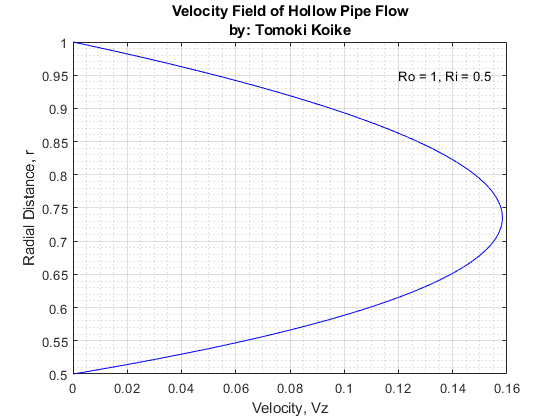

% Defining Variables
ri = 0.5; % Inner Radius
ro = 1; % Outer Radius
mo = -5; % Constant term with pressure gradient with outer radius
mi = -1.25; % Constant term with pressure gradient with inner radius

% Interval of the variable r
r = 0.5:0.001:1;

% Defining the velocity field 
Vz = (r.^2 - ri^2) * -1.25 + (ri^2 - ro^2) * log(r ./ ri) / log(ro/ri) * -1.25;

% Plotting 
fig1 = figure(1);
plot(Vz, r, "-b")
title(["Velocity Field of Hollow Pipe Flow","by: Tomoki Koike"])
ylabel("Radial Distance, r")
xlabel("Velocity, Vz")
grid on 
grid minor 
box on
txt = 'Ro = 1, Ri = 0.5';
text(0.12, 0.95,txt);